clc;
clear;

% Load training data and labels
train_data_x = load('data_train.mat');
train_data_y = load('data_train_labels.mat');
% Extracting the actual data from the loaded variables
train_data_x = train_data_x.data_train;
train_data_y = train_data_y.data_train_labels;

% Define label names
label_names = {'normal', 'roller', 'inner', 'outer', ...
               'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Use 'data_train_labels' as your target labels
target_labels = train_data_y';

% Define parameters for your dataset (adjust these based on your specifications)
theta = 14.94 * pi / 180; % Convert contact angle from degrees to radians
n = 17;
d = 0.01; % in meters
D = 0.06; % in meters
fi = 800 / 60; % Convert rpm to Hz

% Preallocate feature matrix
num_columns = numel(train_data_x);
num_features = 9; % Including mean, std, rms, skewness, kurtosis, 1st harmonic, 2nd harmonic, crest factor, impulse factor, and clearance factor
time_domain_features = zeros(num_columns, num_features);

% Compute and populate the time domain feature matrix
for col = 1:num_columns
    data = train_data_x{col};
    mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    first_order_harmonic = fft_normalized(2);
    second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    time_domain_features(col, :) = [mean_value, std_deviation, rms_value, skewness_value, kurtosis_value, first_order_harmonic, second_order_harmonic, crest_factor,impulse_factor];
end
% Perform PCA (Optional for KNN, included for completeness)
coeff = pca(time_domain_features);
score = time_domain_features * coeff;

% Train K-Nearest Neighbors Classifier
k = 3; % Number of nearest neighbors
knn_model = fitcknn(time_domain_features, label_names(target_labels), 'NumNeighbors', k);

% Load test data and labels
test_data_x = load('data_test.mat');
test_data_y = load('data_test_labels.mat');
test_data_x = test_data_x.data_test;
test_data_y = test_data_y.data_test_labels;

% Preprocess test data to have the same features as training data
num_test_samples = numel(test_data_x);
test_time_domain_features = zeros(num_test_samples, num_features);
for sample = 1:num_test_samples
    data = test_data_x{sample};
    % Compute features for test data
    mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    first_order_harmonic = fft_normalized(2);
    second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    %clearance_factor = max(data) / (max(data) - min(data));
    test_time_domain_features(sample, :) = [mean_value, std_deviation, rms_value, skewness_value, kurtosis_value, first_order_harmonic, second_order_harmonic, crest_factor, impulse_factor];
    %test_time_domain_features(sample, :) = [mean_value, std_deviation, rms_value, skewness_value, kurtosis_value, first_order_harmonic, second_order_harmonic, crest_factor, impulse_factor, clearance_factor];
end

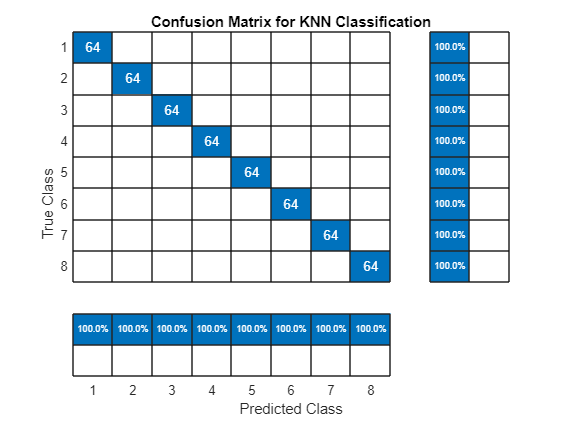

% Predict the labels of the test data using the trained KNN model
predicted_labels = predict(knn_model, test_time_domain_features);

% Convert predicted labels back to numeric if your test_data_y is numeric
predicted_labels_num = cellfun(@(x) find(strcmp(x, label_names)), predicted_labels);

% Create a confusion matrix chart
confMatChart = confusionchart(test_data_y, predicted_labels_num);
confMatChart.Title = 'Confusion Matrix for KNN Classification';
confMatChart.RowSummary = 'row-normalized';
confMatChart.ColumnSummary = 'column-normalized';


% Calculate and display accuracy
accuracy = sum(diag(confMatChart.NormalizedValues)) / sum(confMatChart.NormalizedValues, 'all');
disp(['Accuracy: ', num2str(accuracy * 100), '%']);

Accuracy: 100%


true_labels_cat = categorical(test_data_y, 1:numel(label_names), label_names);
predicted_labels_cat = categorical(predicted_labels_num, 1:numel(label_names), label_names);
[C,order] = confusionmat(true_labels_cat, predicted_labels_cat);
% Assuming 'C' is your confusion matrix and 'order' maps to 'label_names'

% Correct definition of numClasses based on the confusion matrix or label_names
numClasses = size(C, 1); % or numel(label_names)

% Initialize metrics
precision = zeros(numClasses, 1);
recall = zeros(numClasses, 1);
f1Scores = zeros(numClasses, 1);

% Calculate metrics for each class
for i = 1:numClasses
    TP = C(i, i);
    FP = sum(C(:, i)) - TP;
    FN = sum(C(i, :)) - TP;
    
    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);
    f1Scores(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end

% Adjust for any NaN values due to division by zero
precision(isnan(precision)) = 0;
recall(isnan(recall)) = 0;
f1Scores(isnan(f1Scores)) = 0;

% Display the results with actual label names
disp('Class | Precision | Recall | F1 Score');

Class | Precision | Recall | F1 Score


for i = 1:numClasses
    % Use 'order' to fetch the corresponding label name if order is used
    % or directly use 'label_names' if order is not utilized
    label = label_names{i}; % Assuming 'i' aligns with 'label_names' order directly
    fprintf('%s: %.2f | %.2f | %.2f\n', label, precision(i), recall(i), f1Scores(i));
end

normal: 1.00 | 1.00 | 1.00
roller: 1.00 | 1.00 | 1.00
inner: 1.00 | 1.00 | 1.00
outer: 1.00 | 1.00 | 1.00
inner+roller: 1.00 | 1.00 | 1.00
outer+inner: 1.00 | 1.00 | 1.00
outer+inner+roller: 1.00 | 1.00 | 1.00
outer+roller: 1.00 | 1.00 | 1.00
